# Estimación del error en la deflexión de un mástil de bote de vela

Dr. Hermes Pantoja Carhuavilca

## Enunciado

La deflexión $y$ de la punta de un mástil en un bote de vela está dada  por la siguiente fórmula:

donde: 

$F$ es una carga lateral uniforme (N/m), 

$L$ es la altura del mástil (m),

$E$ es el módulo de elasticidad (N/m²),

$I$ es el momento de inercia (m⁴).

Se proporcionan los siguientes valores junto con sus respectivos errores:


$$\tilde{F} = 750 \, \text{N/m}, \quad \Delta \tilde{F} = 30 \, \text{N/m}$$
 


$$\tilde{L} = 9 \, \text{m}, \quad \Delta \tilde{L} = 0.03 \, \text{m}$$



$$\tilde{E} = 7.5 \times 10^9 \, \text{N/m}^2, \quad \Delta \tilde{E} = 5 \times 10^7 \, \text{N/m}^2$$



$$\tilde{I} = 0.0005 \, \text{m}^4, \quad \Delta \tilde{I} = 0.000005 \, \text{m}^4$$


Se pide: Estimar el error en la deflexión $y$ utilizando la propagación de errores.

## Objetivo

El objetivo de esta actividad es calcular la deflexión de la punta de un  mástil en un bote de vela utilizando la fórmula dada y estimar el error  asociado en la deflexión utilizando la propagación de errores.

## Conceptos Teóricos

La propagación de errores se puede generalizar a funciones que sean  dependientes de más de una variable independiente. Sea una función  $q = f(x_1, x_2)$  donde las medidas $\tilde{x}_1$ y $\tilde{x}_2$ tienen  errores $\Delta \tilde{x}_1$ y $\Delta \tilde{x}_2$.

Mediante una versión de la serie de Taylor para el caso de varias variables,  podemos aproximar la función como: 


$$f(x_1, x_2) \approx f(\tilde{x}_1, \tilde{x}_2) + \frac{\partial f}{\partial x_1} \cdot (x_1 - \tilde{x}_1) + \frac{\partial f}{\partial x_2} \cdot (x_2 - \tilde{x}_2)$$


Con lo que el error en $q$ se puede aproximar como: 


$$\xi_q = \Delta f(\tilde{x}_1, \tilde{x}_2) \approx \left| \frac{\partial f}{\partial x_1} \right| \cdot \Delta \tilde{x}_1 + \left| \frac{\partial f}{\partial x_2} \right| \cdot \Delta \tilde{x}_2$$


En nuestro caso, $y = \frac{F L^4}{8EI}$, donde las variables $F$, $L$, $E$, e $I$ son independientes, y podemos calcular el error en la deflexión $y$ utilizando esta aproximación. 

## Preguntas 

- **Calcular la deflexión: **Implementa una función en Matlab que reciba los valores de $F$, $L$, $E$, e $I$ y calcule la deflexión $y$ usando la fórmula dada. 

- **Propagación del error: **Deriva la expresión para la propagación del error en la deflexión $y$. Implementa una función en Matlab que calcule el error en $y$ utilizando  la fórmula de propagación de errores. 

- **Ejecutar los cálculos: **Utiliza las funciones desarrolladas para calcular la deflexión y el error  asociado usando los valores proporcionados. 

- **Investigación adicional:**  ¿Cómo afecta el aumento de cada uno de los parámetros $F$, $L$, $E$, o $I$  la deflexión y su error?. Realiza simulaciones variando cada parámetro  individualmente mientras mantienes los otros constantes. Grafique la relación entre $y$ y una de las variables ( $F$ , $L$ , $E$ ó $I$),  manteniendo los otros parámetros constantes.

**Solución**

Definiendo la función deflexión $y$.

G=@(F,L,E,I) (F*L^4/(8*E*I))

G = function_handle with value:
    @(F,L,E,I)(F*L^4/(8*E*I))


Datos:

Fc=750; % [N/m]
Lc=9;  % [m]
Ec=7.5*1e9; % [N/m^2]
Ic=0.0005; %[m^4]
eF=30; % [N/m]
eL=0.03; % [m]
eE=5*1e7; % [N/m^2]
eI=0.000005; %[m^4]

Fórmula de la propagación de errores: 

syms F L E I
eG=abs(diff(G,F))*eF+abs(diff(G,L))*eL+abs(diff(G,E))*eE+abs(diff(G,I))*eI

$$eG = \frac{15\,{\left|L\right|}^{4}}{4\,\left|\text{E}\right|\,\left|\text{I}\right|}+\frac{3\,\left|F\right|\,{\left|L\right|}^{3}}{200\,\left|\text{E}\right|\,\left|\text{I}\right|}+\frac{5902958103587057\,\left|F\right|\,{\left|L\right|}^{4}}{9444732965739290427392\,\left|\text{E}\right|\,{\left|\text{I}\right|}^{2}}+\frac{6250000\,\left|F\right|\,{\left|L\right|}^{4}}{{\left|\text{E}\right|}^{2}\,\left|\text{I}\right|}$$

Hallando el error absoludo con los valores proporcionados.

%Forma 1
eGFun=matlabFunction(eG,'Vars',{F,L,E,I});
egFun_Value1=eGFun(Fc,Lc,Ec,Ic);
fprintf('Error absoluto de la deflexión: %.6f',egFun_Value1)

Error absoluto de la deflexión: 0.011482

%Forma 2
egFun_Value2=double(subs(eG,{F,L,E,I},{Fc,Lc,Ec,Ic}));
fprintf('Error absoluto de la deflexión: %.6f',egFun_Value2)

Error absoluto de la deflexión: 0.011482

### Simulación

Variando cada parámetro  individualmente mientras se mantiene las otras variables constantes se observa como va variando la deflexión:

Fc=1000 % [N/m]

Fc = 1000

Lc=15  % [m]

Lc = 15

Ec=13.1*1e9 % [N/m^2]

Ec = 1.3100e+10

Ic=0.0001 %[m^4]

Ic = 1.0000e-04

y=G(Fc,Lc,Ec,Ic);
fprintf('Valor de la deflexión variando cada parámetro: %.6f',y)

Valor de la deflexión variando cada parámetro: 4.830630

Como varía su error:

eF=30; % [N/m]
eL=0.03; % [m]
eE=5*1e7; % [N/m^2]
eI=0.000005; %[m^4]
syms F L E I
eG=abs(diff(G,F))*eF+abs(diff(G,L))*eL+abs(diff(G,E))*eE+abs(diff(G,I))*eI;
eGFun=matlabFunction(eG,'Vars',{F,L,E,I});
egFun_Value1=eGFun(Fc,Lc,Ec,Ic);
fprintf('Error absoluto de la deflexión variando cada parámetro: %.6f',egFun_Value1)

Error absoluto de la deflexión variando cada parámetro: 0.443533

Gráfica  entre $y$ y una de las variables ( $F$ , $L$ , $E$ ó $I$),  manteniendo los otros parámetros constantes.

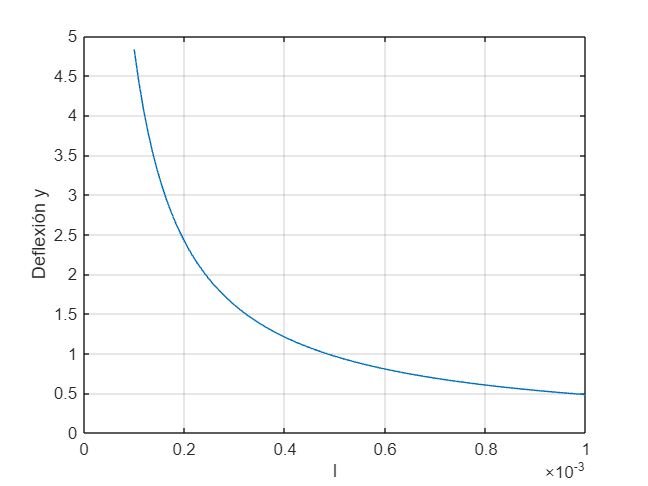

%Seleccione las variables a graficar
selection=4;

% Definición de rangos de variables
xxF = linspace(500, 1000, 100);
xxL = linspace(5, 15, 100);
xxE = linspace(1, 15, 100) * 1e9;
xxI = linspace(0.0001, 0.001, 100);
    switch selection
        case 1 % 'F vs y'
            yy_F = arrayfun(@(F) G(F, Lc, Ec, Ic), xxF);
            plot(xxF, yy_F);
            xlabel('F');
            
        case 2 % 'L vs y'
            yy_L = arrayfun(@(L) G(Fc, L, Ec, Ic), xxL);
            plot(xxL, yy_L);
            xlabel('L');
            
        case 3 % 'E vs y'
            yy_E = arrayfun(@(E) G(Fc, Lc, E, Ic), xxE);
            plot(xxE, yy_E);
            xlabel('E');
            
        case 4 % 'I vs y'
            yy_I = arrayfun(@(I) G(Fc, Lc, Ec, I), xxI);
            plot(xxI, yy_I);
            xlabel('I');
    end
ylabel('Deflexión y');
grid on;